SubjectNr = "001";

dataString = "Data\sleep-cassette\SC4" + SubjectNr + "E0-PSG.edf";
annotationsString = "Data\sleep-cassette\SC4" + SubjectNr + "EC-Hypnogram.edf";

Annotations = edfinfo(annotationsString);
edfInfo = edfinfo(dataString);

numChannels = 3;
blockTime = 30;
fs = 100;

annotatedSleepStages = TransformAnnotatedData(Annotations, blockTime)';

numBlocks = length(annotatedSleepStages);
numSamplesPerBlock = blockTime * fs;

loadedData = loadRealData(edfread(dataString), numSamplesPerBlock, numBlocks, numChannels);

t = linspace(0, numBlocks * blockTime, size(loadedData, 2));

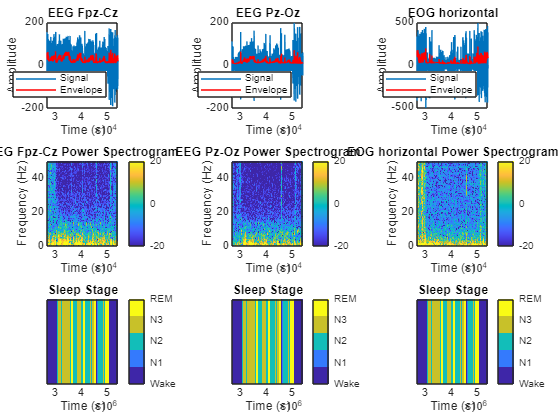


d = 30;
k = 5;
n = 15;


WindowSize = 2 * fs;
Overlap = floor(0.8*WindowSize);
Window = hamming(WindowSize);
Ndft = 2^nextpow2(WindowSize);


firstblock = 900;
finalblock = 1800;

firstSample = firstblock * blockTime * fs;
finalSample = finalblock * blockTime * fs;

tsel = t(firstSample:finalSample-1);
selData = loadedData(:, firstSample:finalSample-1);

dataEnvelopes = cell(numChannels,1);

figure()
tmain = tiledlayout(3, numChannels);   % now 3 rows
tmain.TileSpacing = 'compact';
tmain.Padding = 'compact';

for i = 1:numChannels
    
    % ===== TOP: Time signal =====
    ax1 = nexttile(i);
    plot(ax1, tsel, selData(i,:));
    hold(ax1, "on");

    dataEnvelopes{i} = movmean(abs(hilbert(selData(i,:))), round(blockTime * fs));
    plot(ax1, tsel, dataEnvelopes{i}, 'r');

    title(edfInfo.SignalLabels{i});
    xlabel('Time (s)');
    ylabel('Amplitude');
    xlim(ax1, [tsel(1) tsel(end)]);
    legend(ax1, {'Signal', 'Envelope'}, 'Location', 'southeast');
    hold(ax1, "off");

    % ===== BOTTOM: Power spectrogram =====
    ax2 = nexttile(i + numChannels);

    % Compute power spectrogram
    [S, F, T, P] = spectrogram(selData(i,:), Window, Overlap, Ndft, fs, 'power');

    % Shift time to match waveform
    Treal = T + tsel(1);

    % Plot power spectrogram
    imagesc(ax2, Treal, F, pow2db(P));
    axis(ax2, 'xy');
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(ax2, [edfInfo.SignalLabels{i} ' Power Spectrogram']);

    clim(ax2, [-20 20]);

    xlim(ax2, [tsel(1) tsel(end)]);

    % Colorbar without changing axis width
    colorbar(ax2, 'Location', 'eastoutside');


    % ===== ROW 3: Sleep stage bar =====
    ax3 = nexttile(i + 2 * numChannels);

      % Plot sleep stage transitions as a colored bar
    imagesc(linspace(firstSample, finalSample, finalblock - firstblock), [0,1], annotatedSleepStages(firstblock:finalblock));  
    colormap(ax3, parula(length(unique(annotatedSleepStages))));  % or custom colormap matching sleep staging conventions
   
    set(ax3, 'YTick', []); 
    xlabel('Time (s)');
    title(ax3, 'Sleep Stage');
    c = colorbar(ax3);

    stageLabels = {'Wake','N1','N2','N3','REM'};
    
    % Match colorbar ticks to stage codes 
    c.Ticks = unique(annotatedSleepStages);
    c.TickLabels = stageLabels;
end

% figure();
% 
% for i = 1:numChannels
%     [imf,residual,info] = emd(selData(i, :),Interpolation="pchip", 'MaxNumIMF',3);
% 
%     subplot(1, numChannels, i);
%     hht(imf,fs);
% end

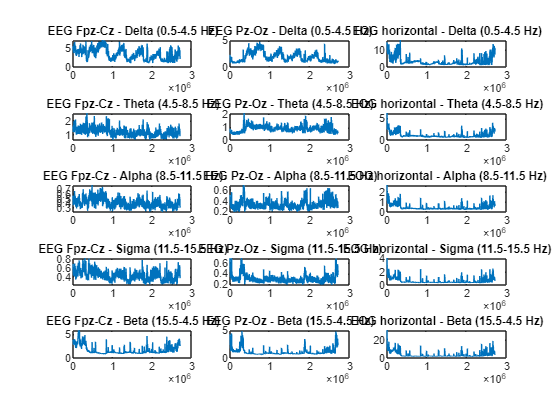



filteredTimeSeries = [];

% freqBands = [0.5, 4.5, 8.5, 11.5, 15.5, 30];
freqBands = [0.5, 4.5; 4.5, 8.5; 8.5 11.5; 11.5, 15.5; 15.5, 30];
% freqBands = [0.5, 4.5; 7.5, 10; 12, 14; 30, 50];

frequencyBandNames = {'Delta', 'Theta', 'Alpha', 'Sigma', 'Beta'};

numBands = length(freqBands);

[phase, amp, dAmp] = preprocessEEG_customBands(selData, fs, freqBands, ...
                                               'FilterOrder', 3000, ...
                                               'DT', 0.002);
figure()
for i = 1:size(dAmp{1}, 1)
    for j = 1:length(dAmp)
        subplot(length(dAmp), size(dAmp{1}, 1), i + ((j-1)*size(dAmp{1}, 1)));
        plot(movmean(abs(dAmp{j}(i, :)), 3000, 2));
        title([edfInfo.SignalLabels{i} , ' - ' , frequencyBandNames{j}, ' (', num2str(freqBands(j)), '-', num2str(freqBands(j+1)), ' Hz)']);
    end
end

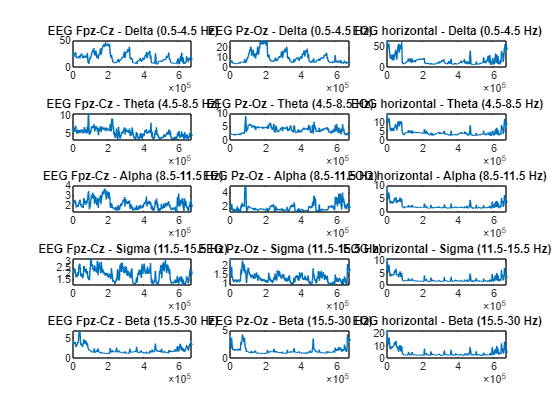



figure()
for i = 1:numChannels

    for j = 1:numBands
        subplot(numBands, numChannels, i + ((j-1)*numChannels));

        [ampEnv, envTime] = extract_band_amplitude(loadedData(i, firstSample:finalSample), fs, [freqBands(j, 1), freqBands(j, 2)], 'ds', 4);
        plot(movmean((ampEnv), 3000));

        title([edfInfo.SignalLabels{i} , ' - ' , frequencyBandNames{j}, ' (', num2str(freqBands(j, 1)), '-', num2str(freqBands(j, 2)), ' Hz)']);
    end
end

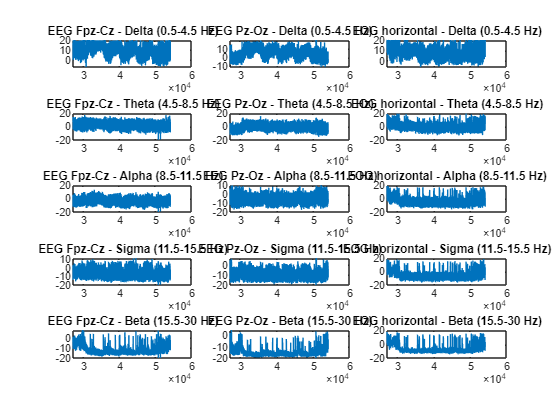


cmin = -20;
cmax = 20;

filteredTimeSeries = [];

figure()
for i = 1:numChannels

    [s, f, t, P] = spectrogram(loadedData(i, firstSample:finalSample),Window,Overlap,Ndft,fs,'power', 'yaxis');
    PdB = pow2db(P);

    PdB_clipped = PdB;
    PdB_clipped(PdB < cmin) = cmin;
    PdB_clipped(PdB > cmax) = cmax;

    for j = 1:numBands
        subplot(numBands, numChannels, i + ((j-1)*numChannels));

        bandData = mean(PdB_clipped(f > freqBands(j, 1) & f < freqBands(j, 2), :), 1);
        filteredTimeSeries = [filteredTimeSeries; bandData];

        plot(Treal, filloutliers(bandData,"clip","movmedian",30));
        title([edfInfo.SignalLabels{i} , ' - ' , frequencyBandNames{j}, ' (', num2str(freqBands(j, 1)), '-', num2str(freqBands(j, 2)), ' Hz)']);
    end
end

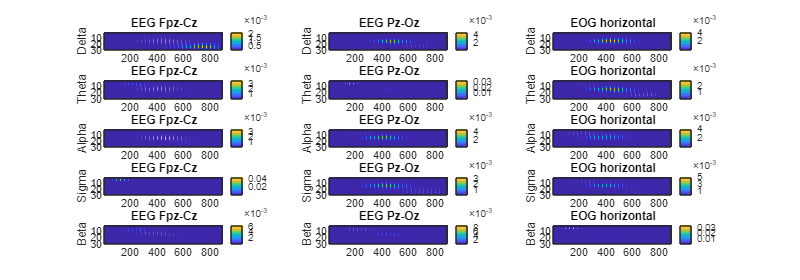


[~, mins, maxs] = NormalizeData(filteredTimeSeries);
[disc_seq,~] = discretize(filteredTimeSeries, d);

selectedBands = [1, 2, 4, 5, 10];
selectedBands = 1:n;

n = length(selectedBands);

P3 = cell(n, 1);
for ii = 1:n
    P3{ii} = ProbabilityTensorGenerate(filteredTimeSeries(selectedBands(ii), :), 3, d);
end

figure('Renderer', 'painters', 'Position', [10 10 2000 700])
colormap parula
num = 1;

for b = 1:numBands
    for ch = 1:numChannels
        subplot(numBands, numChannels, num);
        imagesc(mode_n_matricization(P3{num}, 1));

        colorbar
        title([edfInfo.SignalLabels{ch}])
        ylabel(frequencyBandNames{b})
        num = num + 1;
    end
end



figure()
num = 1;

for b = 1:numBands
    for ch = 1:numChannels
        subplot(numBands, numChannels, num);
        voxel3(P3{num})

        title([edfInfo.SignalLabels{ch}])
        ylabel(frequencyBandNames{b})
        num = num + 1;
    end
end

alpha = 0.05;
rho = 0.9;

cpd_options = {};

cpd_options.maxIter = 2500;
cpd_options.tol = 1e-16;
cpd_options.epsilon = 1/10;
cpd_options.ConvergeVars = false;

[T_hat, O_hats, pi_hat, cpd_output] = multivariate_coupled_cpd_2(P3, k, d, n, alpha, rho, cpd_options);


figure()
subplot(1, 2, 1);
semilogy(cpd_output.tconv);
title("Transition matrix convergence")
ylabel("$\frac{||\hat{T} - \hat{T}_{prev}||_F}{||\hat{T}||_F}$", "Interpreter","latex")
xlabel("iterations")
grid on;

subplot(1, 2, 2);
semilogy(cpd_output.rellrecerr')
title("Tensor reconstruction errors")
ylabel("$||P^n - [[A_n, B_n, C_n]]||_F$", "Interpreter","latex")
xlabel("iterations")
legendLabels = arrayfun(@(i) sprintf('$$\\|P_{%d} - \\hat{P}_{%d}\\|_F$$', i, i), 1:n, 'UniformOutput', false);
legend(legendLabels, 'Interpreter', 'latex');
grid on;

figure();
h = heatmap(T_hat, Colormap=jet());
h.Title = '$T_{hat}$';
h.Interpreter = 'latex';

figure('Position', [10 10 1500 2000]);
num = 0;
for b = 1:numBands
    for ch = 1:numChannels
        num = num + 1;
        subplot(numBands, numChannels, num);
        h = heatmap(O_hats{num}, Colormap=jet());
        % h.Title = "\bf " + edfInfo.SignalLabels{ch};
        % h.YLabel = "\bf " + frequencyBandNames{b};
        % h.XData = {"W", "N1", "N2", "N3", "R"};
        % 
        % h.YDisplayLabels = [num2str(round(mins(num), 1)), repelem("", d-2), num2str(round(maxs(num), 1))];
    end
end



[viterbiPath, delta] = multivariate_viterbi_algorithm(disc_seq(selectedBands, :), T_hat, O_hats, pi_hat, 0.5, 0);


allperms=perms([1:size(T_hat, 1)]);

for ix=1:size(allperms,1)
    out_stages=permute_stages(viterbiPath, allperms(ix,:));
    score_vi(ix)=numel(find(out_stages==annotatedSleepStages(1:end-1)))/numel(annotatedSleepStages(1:end-1));
end 

[msc,idx]=max(score_vi); % this finds the permutations with the best score and saves the index of the best permutation in idx.

viterbiPath = permute_stages(viterbiPath, allperms(idx,:));

T_hat = T_hat(allperms(idx,:), allperms(idx,:));

for i = 1:n
    O_hat = O_hats{i};
    O_hats{i} = O_hat(:, allperms(idx,:));
end

m = length(vPath);

figure();

cmap = [0,0,0; parula(k)];
colormap(cmap);

subplot(3, 1, 1);
imagesc(1:length(annotatedSleepStages), [0 1], annotatedSleepStages);
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",12);
title("True sleep stages")


subplot(3, 1, 2);
imagesc(1:m, [0 1], viterbiPath(1:m));
clim([1 k+1]);
ylabel("States", "Interpreter", "latex","FontSize",15);
set(gca,'YTickLabel',[]);
xlabel("Time [$s$]", "Interpreter", "latex","FontSize",12);
title("Viterbi estimated sleep stages")

% --- Add legend as an invisible axes at the bottom ---
legend_ax = subplot(3, 1, 3);
axis off;  % Hide this subplot

% Create dummy handles for legend colors
hold on;
legendHandles = gobjects(k,1);
for i = 1:k
    legendHandles(i) = plot(nan, nan, 's', ...
        'MarkerFaceColor', cmap(i+1,:), ...
        'MarkerEdgeColor', cmap(i+1,:), ...
        'MarkerSize', 10);
end

legend(legendHandles, arrayfun(@(x) sprintf('State %d', x), 1:k, 'UniformOutput', false), ...
       'Orientation', 'horizontal', ...
       'Location', 'southoutside', ... 
       'FontSize', 12);
